
% make sure we have copies of the two example files in the main directory
if exist('Data/validation')%#ok
    copyfile 'Data/validation/v (1).m4a';
    copyfile 'Data/validation/v (10).m4a';
end

Add current folder and subfolders to search path, so the script can find the recordings in subdirectories of "Data", and various MATLAB functions in "HelperFunctions".

addpath(genpath(pwd));
addpath('./HelperFunctions');
warning off;                      % suprress warning messages

The remainder of this demo is structured according to the four phases of the typical machine learning workflow:

- Access and Explore Data

- Preproess Data

- Develop Predictive Models

- Integrate Models with Systems

The figure below shows which additional MATLAB toolboxes we will leverage in the various phases of the workflow.

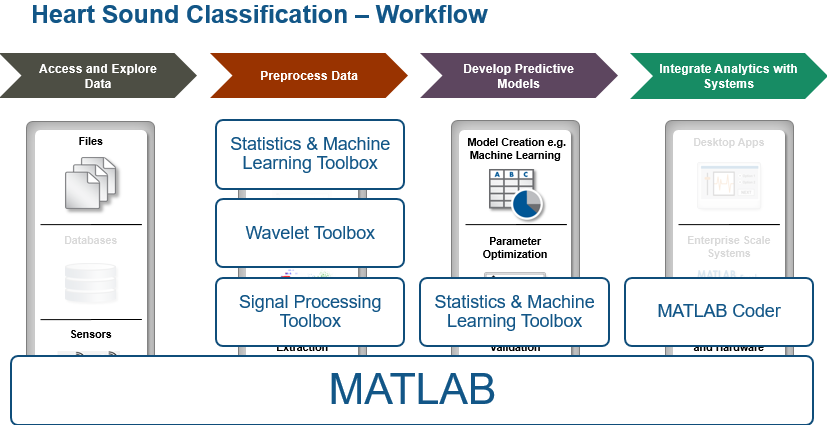

## 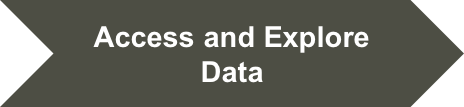

## What does a cough sound like?

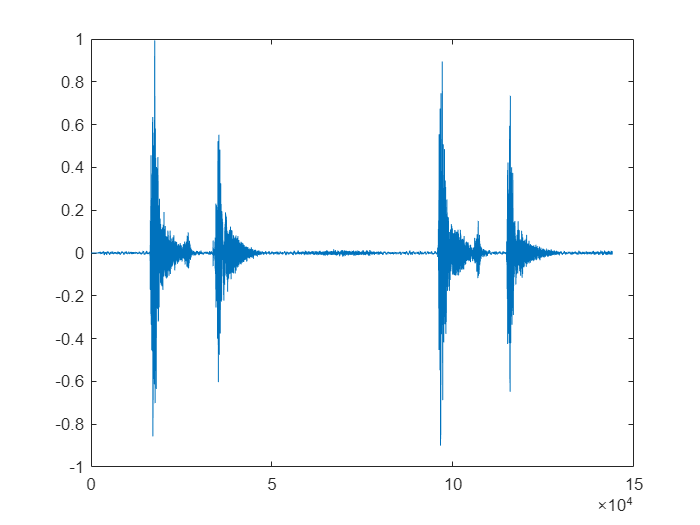

[Cough, fs] = audioread('v (1).m4a');
p_cough = audioplayer(Cough, fs);
play(p_cough, [1 (get(p_cough, 'SampleRate') * 3)]);

% Plot the sound waveform
plot(Cough(1:fs*3))

## What does a breath sound like?

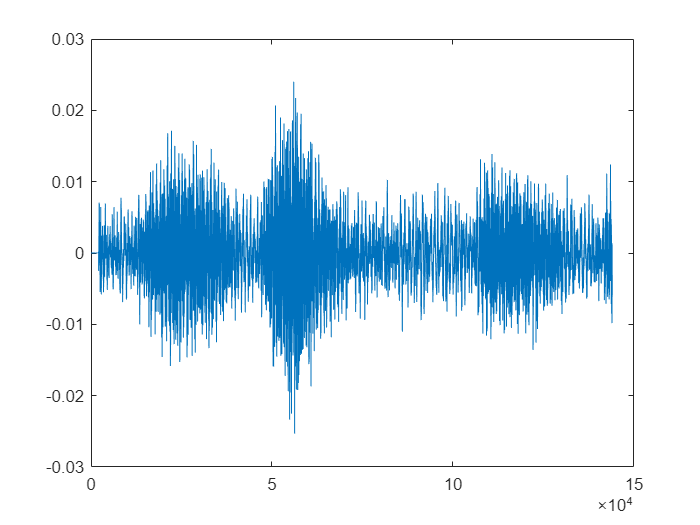

[Breath, fs] = audioread('v (10).m4a');
p_normal = audioplayer(Breath, fs);
play(p_normal, [1 (get(p_normal, 'SampleRate') * 3)]);

% Plot the sound waveform
plot(Breath(1:fs*3))

## 

## What do the signals look like in the frequency domain?

To explore what we might use to distinguish these signals with a classifier, let's look at their frequency content. To this end, you can use MATLAB's [Signal Analyzer](https://www.mathworks.com/help/signal/ug/getting-started-with-signal-analyzer-app.html) app to inspect and compare the power spectrum of the two signals.

signalAnalyzer(Breath, Cough)

## 

## Prepare to read the data into memory

To load the recordings into memory, MATLAB's [fileDatastore](https://www.mathworks.com/help/matlab/ref/filedatastore.html) provides a convenient way to handle a large number of data files spread across multiple folders. The read function provides flexibility to access a wide variety of different file formats, and with MATLAB's base read functions typically little customization is needed. 

% expecting the training data in subfolders of 'Data\training\*': "training-a", etc
training_fds = fileDatastore(fullfile(pwd, 'Data', 'training'), 'ReadFcn', @importAudioFile, 'FileExtensions', '.m4a','IncludeSubfolders',true);
   validation_dir = './Data/validation';
   reference_validation = importReferencefile([validation_dir '/REFERENCE.csv']);
   validation_fds = fileDatastore(validation_dir, 'ReadFcn', @importAudioFile, 'FileExtensions', '.m4a');
    
  

## 

## Create a table with filenames and labels

"Labels" (or also "ground truth") represent the true category of each sample in a dataset and are critical to be able to apply  "supervised" machine learning to this classification task. The dataset we are using here provides the labels in a separate REFERENCE file in each subfolder of the training and validation data, along with the corresponding audio files (recordings). So in this section we read these REFERENCE.csv files and build a table with filename and corresponding label. This step is only needed if you want to run feature extraction in the next step.

data_dir = fullfile(pwd, 'Data', 'training');
folder_list = dir([data_dir filesep 'training*']);

reference_table = table();
for ifolder = 1:length(folder_list)
    disp(['Processing files from folder: ' folder_list(ifolder).name])
    current_folder = [data_dir filesep folder_list(ifolder).name];
    
    % Import ground truth labels (1, -1) from reference. 1 = Breath, -1 = Cough
    reference_table = [reference_table; importReferencefile([current_folder filesep 'REFERENCE.csv'])];
end

Processing files from folder: training-a


## 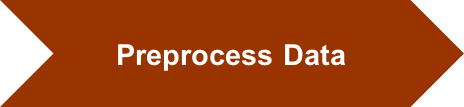

## Extract features from raw  sound signals

runExtraction = false; % control whether to run feature extraction (will take several minutes)
   % Note: be sure to have the training data downloaded before executing
   % this section!
if runExtraction | ~exist('FeatureTable.mat') |~exist('ValidationTable.mat')%#ok 
    % Window length for feature extraction in seconds
    win_len = 5;
    
    % Specify the overlap between adjacent windows for feature extraction in percentage
    win_overlap = 0;
    
    % Initialize feature table to accumulate observations
    feature_table = table();
    validation_table=table();
    % Use Parallel Computing Toobox to speed up feature extraction by distributing computation across available processors
    
    % Create partitions of the fileDatastore object based on the number of processors
    n_parts = numpartitions(training_fds, gcp);
    n_parts_val=numpartitions(validation_fds, gcp);
    
    % Note: You could distribute computation across available processors by using 
    % parfor instead of "for" below, but you'll need to omit keeping track
    % of signal lengths
    parfor ipart = 1:n_parts
        % Get partition ipart of the datastore.
        subds = partition(training_fds, n_parts, ipart);
        % Extract features for the sub datastore
        [feature_win,sampleN] = extractFeatures(subds, win_len, win_overlap, reference_table);
        
        % and append that to the overall feature table we're building up
        feature_table = [feature_table; feature_win];
        
        % Display progress
        disp(['Part ' num2str(ipart) ' done.'])
    end
    parfor ipart = 1:n_parts_val
        % Get partition ipart of the datastore.
        subds_val = partition(validation_fds, n_parts_val, ipart);
        
        % Extract features for the sub datastore
        [feature_win,sampleN] = extractFeatures(subds_val, win_len, win_overlap, reference_validation);
        
        % and append that to the overall feature table we're building up
        validation_table = [validation_table; feature_win];
        
        % Display progress
        disp(['Part ' num2str(ipart) ' done.'])
    end
    save('FeatureTable', 'feature_table');
    save('ValidationTable','validation_table');
else % simply load the precomputed features
    load('FeatureTable.mat');
    load('ValidationTable.mat');
end

% Take a look at the feature table
disp(feature_table(1:5,:))

     meanValue     medianValue    standardDeviation    meanAbsoluteDeviation    quantile25    quantile75    signalIQR    sampleSkewness    sampleKurtosis    signalEntropy    spectralEntropy    dominantFrequencyValue    dominantFrequencyMagnitude    dominantFrequencyRatio    MFCC1      MFCC2       MFCC3      MFCC4      MFCC5      MFCC6      MFCC7      MFCC8       MFCC9     MFCC10     MFCC11     MFCC12     MFCC13        class    
    ___________    ___________    ________________

## 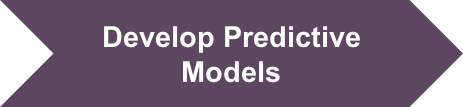

## Train, compare and select classifier 

Having an initial set of features, we can proceed to the next phase of the machine learning workflow, the training of various predictive models. You can use the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) to interactively train, compare and select classifiers.

classificationLearner

## Optimize the model using misclassification cost

% tabulate classes in training data
grpstats_all = grpstats(feature_table, 'class', 'mean');
disp(grpstats_all(:,'GroupCount'))

                GroupCount
                __________

    Abnormal        22    
    Normal          19    



## 

## To train and optimize models programmatically, you perform the following steps:

- Explicitly split your data into a training and test set, which you set aside for assessing accuracy

- Train a model using the 'Cost' and 'OptimizeHyperparameters' parameters

- Evaluate accuracy of model on held-out test set


training_set=feature_table;
test_set=validation_table;

## Train the classifier (programmatically) with misclassification cost

Like we did interactively above, we compensate for fewer 'Abnormal' observations in the data, and  bias the classifier towards fewer misclassifications of abnormal sounds, using a cost matrix that assigns higher misclassification cost to the 'Abnormal' class. At the same time, we perform hyperparameter tuning by using [Bayesian Optimization](https://www.mathworks.com/help/stats/bayesian-optimization-workflow.html) to find optimal values for model parameters. 

Since the ensemble of trees outperformed the SVM classifier in the Classification Learner, we continue with the ensemble. 

% Assign higher cost for misclassification of cough sounds
C = [0, 10; 1, 0];        

% Create a random sub sample (to speed up training) of 1/4 of the training set
%subsample = randi([1 height(training_set)], round(height(training_set)/4), 1);
% OR train on the whole training set
subsample = 1:height(training_set);

rng(1);

% Create a 5-fold cross-validation set from training data
cvp = cvpartition(length(subsample),'KFold',5);

% Step 2: train the model with hyperparameter tuning (unless you simply
% load an existing pre-trained model)

% train ensemble of decision trees (random forest)
disp("Training Ensemble classifier...")

Training Ensemble classifier...


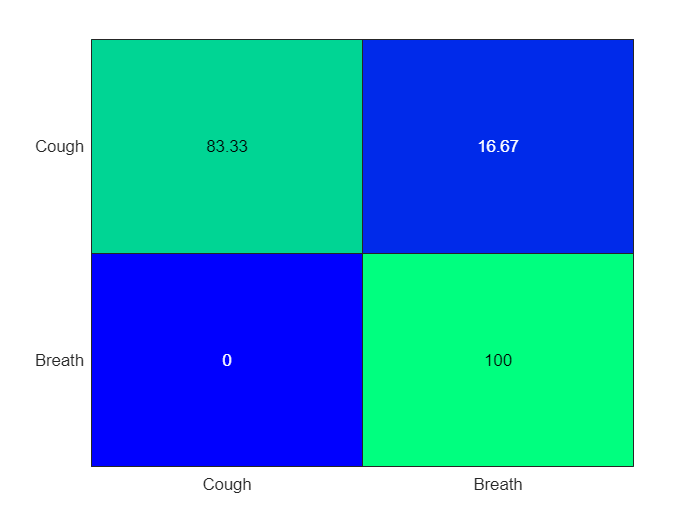

if ~exist("TrainedModel.mat")
% bayesian optimization parameters (stop after 15 iterations)
    opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus'); 
        
    trained_model = fitcensemble(training_set(subsample,:),'class','Cost',C,...
        'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'},...
        'HyperparameterOptimizationOptions',opts);
    save("TrainedModel.mat","trained_model");
    else
    load("TrainedModel.mat");
end
    
% Step 3: evaluate accuracy on held-out test set

% Predict class labels for the validation set using trained model
% NOTE: if training ensemble without optimization, need to use trained_model.Trained{idx} to predict
predicted_class = predict(trained_model, test_set);

conf_mat = confusionmat(test_set.class, predicted_class);

conf_mat_per = conf_mat*100./sum(conf_mat, 2);

% Visualize model performance in heatmap
labels = {'Cough', 'Breath'};
heatmap(labels, labels, conf_mat_per, 'Colormap', winter, 'ColorbarVisible','off');

## 

## Perform feature selection using Neighborhood Component Analysis

The last model performs pretty well, but it is too large for deployment on a small embedded device. Therefore, in this section we explore training a more compact model that uses only a subset of the 26 features, namely the features that have the majority of the predictive power. [Neighborhood Component Analysis](https://www.mathworks.com/help/stats/neighborhood-component-analysis.html) (NCA) is an automated approach for  selecting a small subset of features that carry information most relevant to the classification task while minimizing redudancy among selected features. 

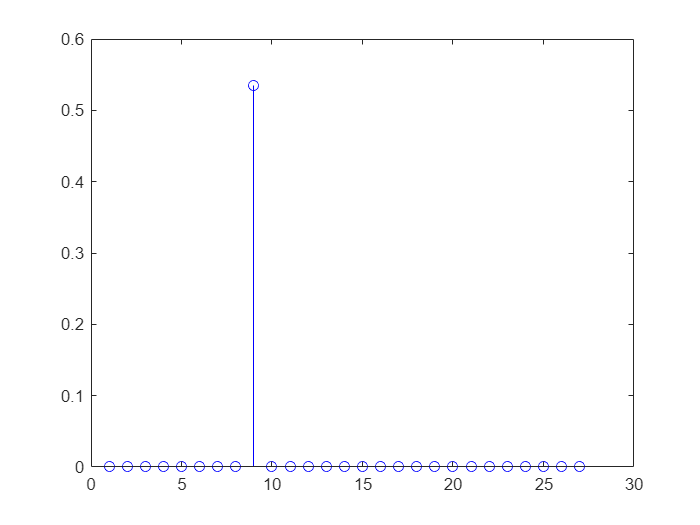

runNCA = true;   % control whether to see NCA running or just load the selected features
    
if ~runNCA && exist('SelectedFeatures.mat')%#ok
    % Load saved array of selected feature indexes
    load('SelectedFeatures.mat')
else % Perform feature selection with neighborhood component analysis
    rng(1);
    
    % first, let's make sure we've split the data (in case we skipped the
    % programmatic model training sections above)
    if ~exist('training_set')
        [training_set, test_set] = splitDataSets(feature_table,0.3);
    end
    
    mdl = fscnca(table2array(training_set(:,1:27)), ...
        table2array(training_set(:,28)), 'Lambda', 0.005, 'Verbose', 0);
    
    % Select features with weight above 1
    selected_feature_indx = find(mdl.FeatureWeights > 0.1);

    % Plot feature weights
    stem(mdl.FeatureWeights,'bo');
    
    % save for future reference
    save('SelectedFeatures', 'selected_feature_indx');
end


% Display list of selected features
disp(feature_table.Properties.VariableNames(selected_feature_indx))

    {'sampleKurtosis'}



## 

## Train model with selected features

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |
|====================================================================================================================|
|    1 | Best   |           0 |      1.5272 |           0 |           0 |  GentleBoost |           25 |    0.0024335 |
|    2 | Accept |     0.46341 |     0.57773 |           0 |    0.018426 |     RUSBoost |          192 |    0.0045176 |
|    3 | Accept |     0.46341 |      4.9787 |           0 |     0.06115 |          Bag |          137 |            - |
|    4 | Accept |     0.46341 |     0.15134 |           0 |  3.4756e-05 |     RUSBoost |           17 |     0.054548 |
|    5 | Accept |           0 |     0.50397 |   

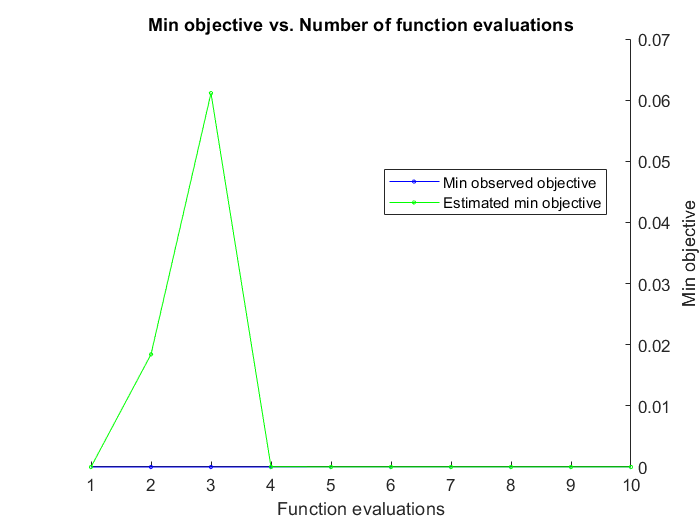


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 10 reached.
Total function evaluations: 10
Total elapsed time: 28.9216 seconds
Total objective function evaluation time: 22.5395

Best observed feasible point:
      Method       NumLearningCycles    LearnRate
    ___________    _________________    _________

    GentleBoost           25            0.0024335

Observed objective function value = 0
Estimated objective function value = 1.0298e-05
Function evaluation time = 1.5272

Best estimated feasible point (according to models):
      Method      NumLearningCycles    LearnRate
    __________    _________________    _________

    LogitBoost           20            0.003726 

Estimated objective function value = 1.0298e-05
Es

trained_model_featsel =   ClassificationEnsemble
                       PredictorNames: {'sampleKurtosis'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'Abnormal'  'Normal'}
                       ScoreTransform: 'none'
                      NumObservations: 41
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 20
                               Method: 'LogitBoost'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [20×1 double]
                   FitInfoDescription: {2×1 cell}


  Properties, 

trainReducedModel = false;    % control whether to re-train this model or load it from a previous run

if trainReducedModel | ~exist('TrainedEnsembleModel_FeatSel.mat')%#ok
    % configure key parameters: cross validation, cost, and hyperparameter
    % tuning
    rng(1)
    cvp = cvpartition(length(subsample),'KFold',5);
    C = [0, 100; 1, 0];            % Assign higher cost for misclassification of abnormal heart sounds
    opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',10);    
    
    % now we are ready to train...
    trained_model_featsel = fitcensemble(training_set(subsample,selected_feature_indx),training_set.class(subsample),'Cost',C,...
        'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'}, 'HyperparameterOptimizationOptions',opts)
     %save the model for later reference
    save('TrainedWaveletModel_FeatSel', 'trained_model_featsel');
else
    load('TrainedEnsembleModel_FeatSel.mat')
end

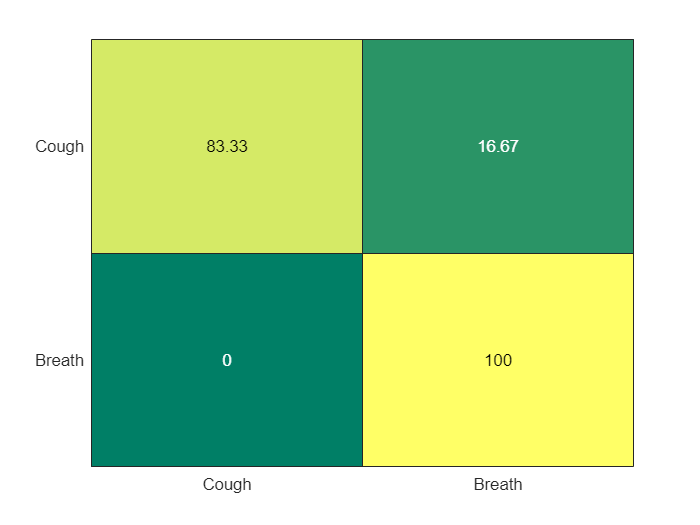


% Predict class labels for the validation set using trained model
predicted_class_featsel = predict(trained_model_featsel, test_set(:,selected_feature_indx));

conf_mat_featsel = confusionmat(test_set.class, predicted_class_featsel);

conf_mat_per_featsel = conf_mat_featsel*100./sum(conf_mat_featsel, 2);

labels = {'Cough', 'Breath'};

% Visualize model performance
% probably custom AE version: heatmap(conf_mat_per_featsel, labels, labels, 1,'Colormap', 'red','ShowAllTicks',1,'UseLogColorMap',false,'Colorbar',true);
heatmap(labels,labels,conf_mat_per_featsel, 'Colormap', summer, 'ColorbarVisible','off');

## 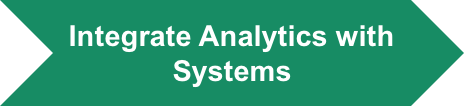

## Code Generation

Generate C code that takes recorded signal and sampling frequency as input and produces heart sound classification label as output. 

Instead of running codegen on the command line, if you were familiar with the Coder App and wanted to highlight this capability, you could bring up MATLAB Coder.


coder

## Validate final model

Process a random subset of audio files from the validation set by the sample app. The app calls the mex version of the function "classifyHeartSounds"

plotPredictions

Error using fileDatastore (line 227)
Input folders or files do not contain specified file extensions: .wav

Error in plotPredictions (